y''' + y'' + y' + y = 2x - 1, 

y(0) = 1, y'(0) = 0, y''(0) = 0

% Define the ODE
f = @(x, y) [y(2); y(3); 2*x - 1 - y(3) - y(2) - y(1)];

% Define the initial conditions
y0 = [1; 0; 0];

% Define the exact solution
y_exact = @(x) 2*x + 2*exp(-x) + 2*cos(x) - 3;

% Define the time interval and step size
t0 = 0;
tf = 10000;
h = 0.1;
tspan = t0:h:tf;

% Use the Adams-Bashforth method to approximate the solution
tic;
[t_AB, y_AB] = adams_bashforth(f, y0, tspan, h);
time_AB = toc * 1000;

% Use the Adams-Moulton method to approximate the solution
tic;
[t_AM, y_AM] = adams_moulton(f, y0, tspan, h);
time_AM = toc * 1000;

% Calculate the exact solution
y_exact_sol = y_exact(tspan);

y_AB_t = y_AB(:,1).'

y_AB_t = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007


y_AM_t = y_AM(:,1).'

y_AM_t = 1.0e+04 *

    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0005    0.0005    0.0006    0.0006    0.0006    0.0007    0.0007



% Calculate the errors
error_ab = abs(y_AB_t - y_exact_sol);
error_am = abs(y_AM_t - y_exact_sol);

% Error per
per_error_arr_ab = abs(error_ab ./ y_exact_sol * 100)

per_error_arr_ab =          0    0.0317    0.2411    0.3887    0.4196    0.4910    0.5188    0.5271    0.5105    0.4695    0.4025    0.3071    0.1799    0.0169    0.1869    0.4357    0.7324    1.0757    1.4569    1.8566    2.2432    2.5763    2.8159    2.9356    2.9312    2.8200    2.6321    2.3996    2.1496    1.9011    1.6659    1.4499    1.2552    1.0820    0.9289    0.7941    0.6757    0.5717    0.4803    0.4000    0.3292    0.2670    0.2120    0.1635    0.1207    0.0829    0.0496    0.0202    0.0056    0.0283


per_error_arr_am = abs(error_am ./ y_exact_sol * 100)

per_error_arr_am =          0    0.0317    0.2411    0.3789    0.4823    0.5526    0.5958    0.6132    0.6053    0.5716    0.5105    0.4193    0.2943    0.1307    0.0772    0.3347    0.6457    1.0102    1.4202    1.8564    2.2858    2.6650    2.9497    3.1087    3.1342    3.0419    2.8625    2.6299    2.3732    2.1138    1.8650    1.6341    1.4242    1.2358    1.0679    0.9190    0.7872    0.6706    0.5674    0.4759    0.3948    0.3228    0.2587    0.2017    0.1509    0.1056    0.0652    0.0293    0.0027    0.0311



% Mean Error Per
mean_error_ab = mean(per_error_arr_ab(2:end))

mean_error_ab = 0.0124

mean_error_am = mean(per_error_arr_am(2:end))

mean_error_am = 0.0041

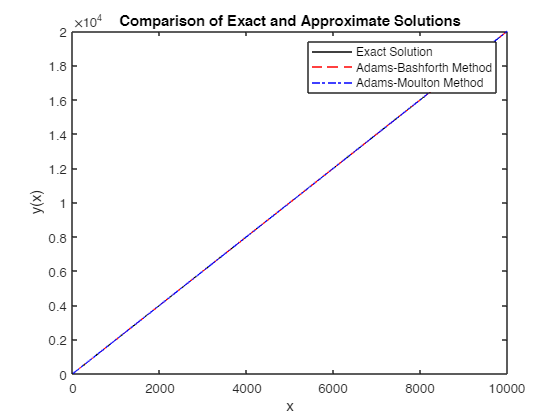


% Plot the results
figure;
plot(t_AB, y_exact_sol, 'black-', t_AB, y_AB(:,1), 'r--', t_AM, y_AM(:,1), 'b-.');
xlabel('x');
ylabel('y(x)');
title('Comparison of Exact and Approximate Solutions');
legend('Exact Solution', 'Adams-Bashforth Method', 'Adams-Moulton Method');


% Print the time taken for each method
fprintf('Time taken for Adams-Bashforth method: %f milliseconds\n', time_AB);

Time taken for Adams-Bashforth method: 157.757400 milliseconds


fprintf('Time taken for Adams-Moulton method: %f milliseconds\n', time_AM);

Time taken for Adams-Moulton method: 262.176300 milliseconds


function [t, y] = adams_bashforth(f, y0, tspan, h)
% Solve an ODE using the Adams-Bashforth method

% Initialize the solution
t = tspan;
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Use the Euler method to compute the first three values of y
for i = 2:3
    y(i, :) = y(i-1, :) + h*f(t(i-1), y(i-1, :))';
end

% Use the Adams-Bashforth method to compute the remaining values of y
for i = 3:length(t)-1
    y(i+1,:) = y(i,:) + (h/12)*(23*f(t(i), y(i,:)) - 16*f(t(i-1), y(i-1,:)) + 5*f(t(i-2), y(i-2,:)))';
end
end


function [t, y] = adams_moulton(f, y0, tspan, h)
% Solve an ODE using the Adams-Moulton method

% Initialize the solution
t = tspan;
y = zeros(length(t), length(y0));
y(1,:) = y0;

% Use the Euler method to compute the first three values of y
for i = 2:3
    y(i, :) = y(i-1, :) + h*f(t(i-1), y(i-1, :))';
end

% Use the Adams-Moulton method to compute the remaining values of y
for i = 3:length(t)-1
    % Adams-Bashforth Order 3 (yn+3)
    y_predictor = y(i,:) + (h/12)*(23*f(t(i), y(i,:)) - 16*f(t(i-1), y(i-1,:)) + 5*f(t(i-2), y(i-2,:)))';
    % Corrector using Adams-Moulton method of order 3 (yn+2)
    y_corrector = y(i,:) + (h/12)*(5*f(t(i+1), y_predictor) + 8*f(t(i), y(i,:)) - f(t(i-1), y(i-1,:)))';
    y(i+1,:) = y_corrector;
end

end
